
data_dip9 = load('calib_BI_DIP9.dat');
I9raw = data_dip9(:,1);
B9raw = data_dip9(:,4); 

% btemp = (B9raw(30) + B9raw(31))./2;
% itemp = (I9raw(30) + I9raw(31))./2;
% B9 = [B9raw(1:29);btemp; B9raw(32:end)];
% I9 = [I9raw(1:29);itemp; I9raw(32:end)];

B9 = B9raw;
I9 = I9raw;

% data_dip91 = load('calib_BI_DIP91.dat');
% I91 = data_dip91(:,1);
% B91 = data_dip91(:,4); 
% 
% data_dip7 = load('calib_BI_DIP7.dat');
% I7 = data_dip7(:,1);
% B7 = data_dip7(:,4); 
% 
% data_dip11 = load('calib_BI_DIP11.dat');
% I11 = data_dip11(:,1);
% B11 = data_dip11(:,4); 
% 
% data_dip12 = load('calib_BI_DIP12.dat');
% I12 = data_dip12(:,1);
% B12 = data_dip12(:,4); 



%%


figure
set(gca,'FontSize',20)
plot(I9, B9, 'bo-', 'MarkerSize',6, 'LineWidth',1.2)
% hold on
% plot(I91, B91, 'bd-', 'MarkerSize',6, 'LineWidth',1.2)
% plot(I7, B7, 'ro-', 'MarkerSize',6, 'LineWidth',1.2)
% plot(I11, B12, 'go-', 'MarkerSize',6, 'LineWidth',1.2)
% plot(I12, B12, 'mo-', 'MarkerSize',6, 'LineWidth',1.2)
% hold off
xlabel(' Current [A]')
ylabel('Inegrated field [T m]')
u = legend('DIP-9', 'DIP-91','DIP-7','DIP-11', 'DIP-12');

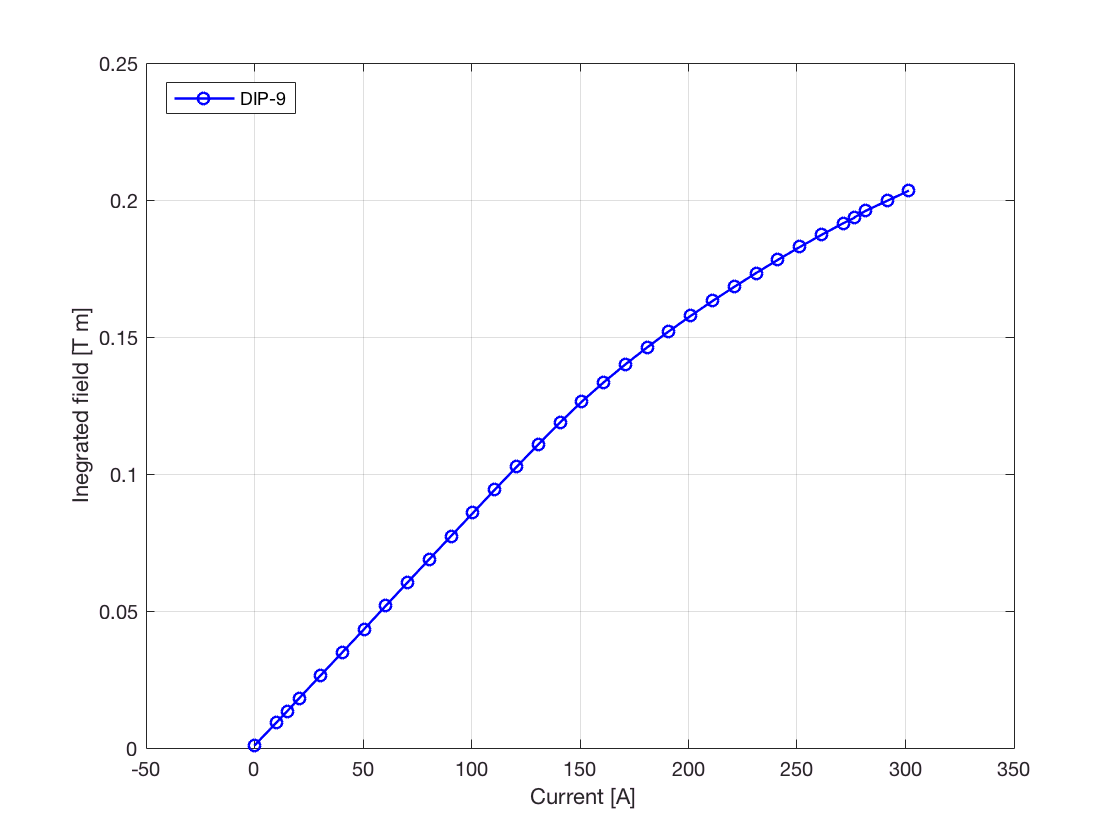

set(u,'Location','NorthWest')


xx9 = linspace(min(I9),max(I9),5*length(I9));
yy9 = spline(I9,B9,xx9);
ii9 = interp1(I9,B9,xx9); 

p9 = polyfit(I9,B9,7)

p9 =    1.0e-03 *

   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0009    0.8593    0.7888


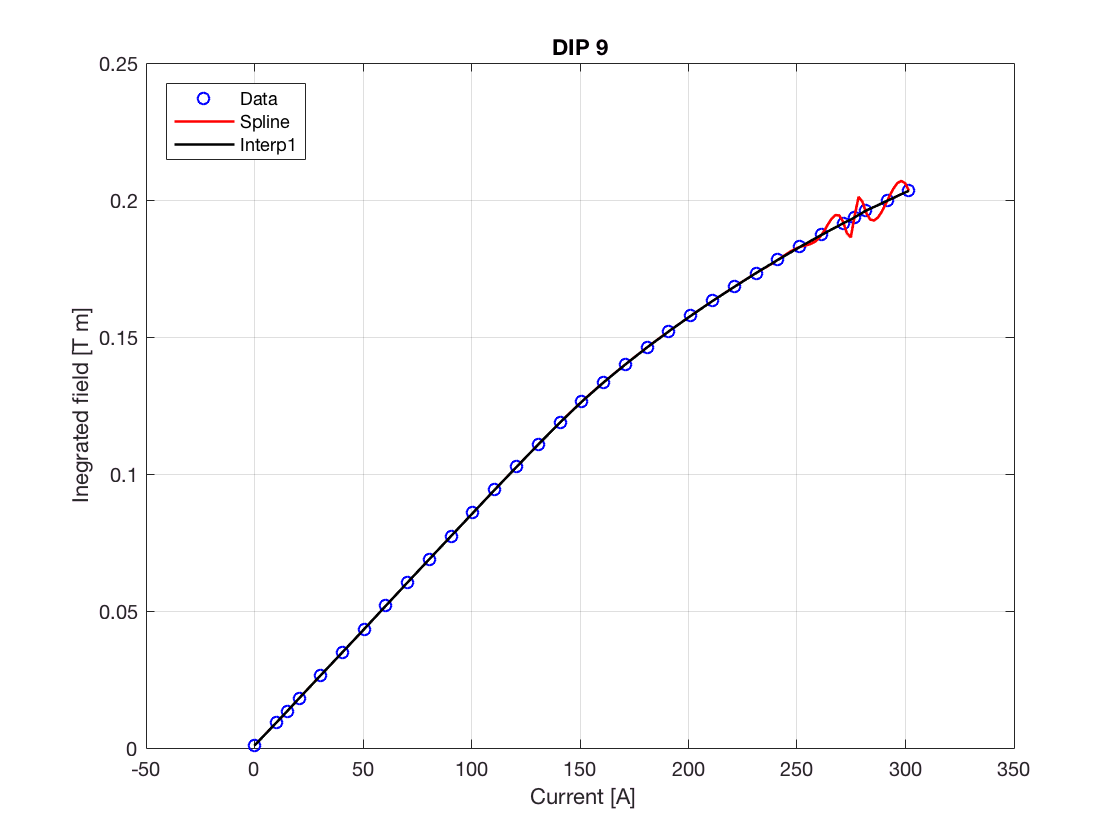


%x = linspace(min(I8),max(I8),3*length(I8));
f9 = polyval(p9,xx9);

figure
set(gca,'FontSize',20)
plot(I9, B9, 'bo', 'MarkerSize',6)
hold on
plot(xx9, yy9, 'r-', 'Linewidth',1.3)
plot(xx9, ii9, 'k-', 'Linewidth',1.3)
hold off
title('DIP 9')
xlabel(' Current [A]')
ylabel('Inegrated field [T m]')
u = legend('Data','Spline', 'Interp1');
set(u,'Location','NorthWest')

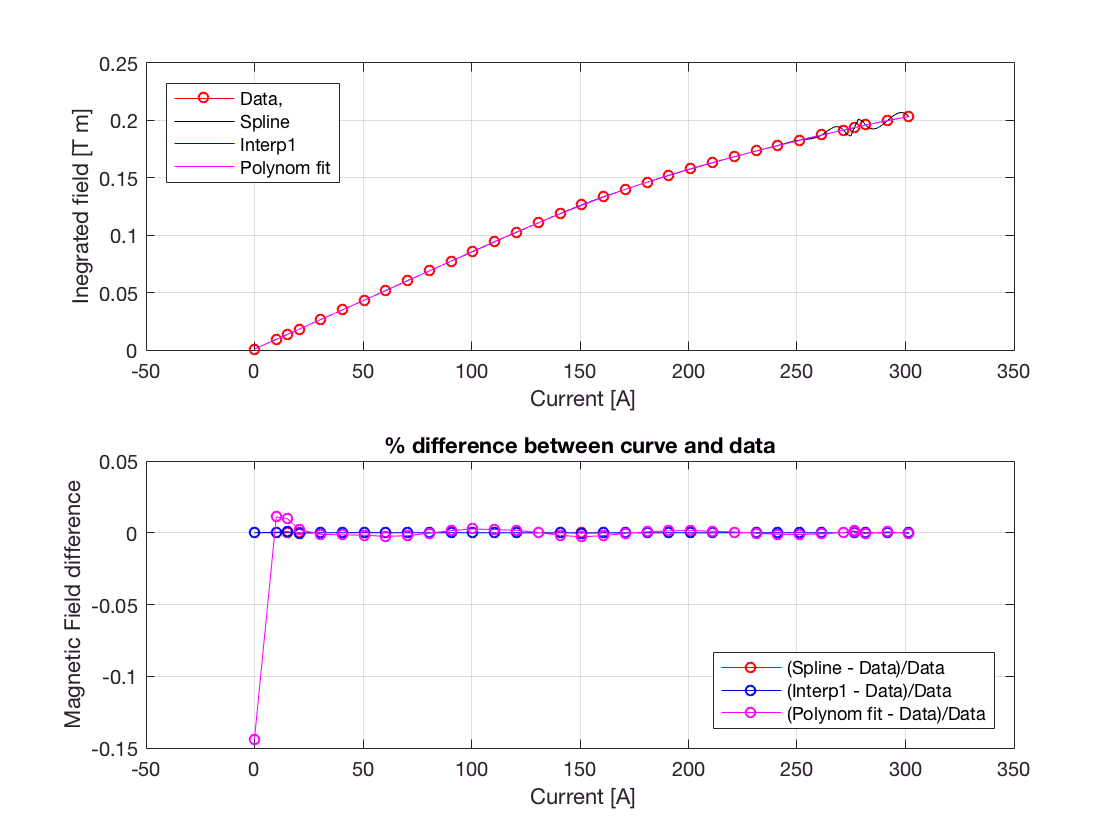



figure;
subplot(2,1,1);
set(gca,'FontSize',20)
plot(I9,B9,'-ro',xx9,yy9,'k',xx9,ii9,'b',xx9,f9,'m','MarkerSize',5);
u=legend('Data,','Spline','Interp1','Polynom fit');
set(u,'Location','NorthWest')
xlabel(' Current [A]')
ylabel('Inegrated field [T m]')
subplot(2,1,2);
set(gca,'FontSize',20)
plot(I9,(spline(xx9,yy9,I9) - B9)./B9,'ro-',...
     I9,(interp1(xx9,ii9,I9) - B9)./B9,'bo-',...
     I9,(polyval(p9,I9) - B9)./B9,'mo-','MarkerSize',5);

u = legend('(Spline - Data)/Data','(Interp1 - Data)/Data','(Polynom fit - Data)/Data');
set(u,'Location','SouthEast')
xlabel(' Current [A]')
ylabel('Magnetic Field difference')
title('% difference between curve and data');

%% Current range fitting

B9_reg1 = B9(1:10);
I9_reg1 = I9(1:10);

B9_reg2 = B9(10:end);
I9_reg2 = I9(10:end);

x1 = linspace(min(I9_reg1),max(I9_reg1),5*length(I9_reg1));
x2 = linspace(min(I9_reg2),max(I9_reg2),5*length(I9_reg2));

%%


p9 = polyfit(I9_reg2,B9_reg2,7)

p9 =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0001    0.0034   -0.0423



f9 = polyval(p9,x2);

% Linear fit
pl9 = polyfit(I9_reg1,B9_reg1,1)

pl9 =    1.0e-03 *

    0.8451    0.7702



fl9 = polyval(pl9,x1);

T91 = table(I9_reg1,B9_reg1,polyval(pl9,I9_reg1),B9_reg1-polyval(pl9,I9_reg1),100*(polyval(pl9,I9_reg1) - B9_reg1)./B9_reg1,'VariableNames',{'I','B','Fit','FitError','RelFitError'})

T91 =         I            B            Fit         FitError      RelFitError
    _________    __________    __________    ___________    ___________

    -0.062303    0.00085924    0.00071754      0.0001417      -16.491  
       10.056     0.0092497     0.0092686     -1.892e-05      0.20455  
       15.111      0.013478       0.01354    -6.2021e-05      0.46015  
       20.552      0.018135      0.018139    -3.7855e-06     0.020874  
       30.624      0.026632      0.026651    -1.8946e-05      0.07114  
       40.614      0.035022      0.035094    -7.1745e-05      0.20486  
       50.551      0.043408      0.043491    -8.3091e-05      0.19142  
       60.575      0.051958      0.051962    -4.4542e-06    0.0085728  
        70.49      0.060399      0.060341     5.8089e-05    -0.096175  
       80.467      0.068836    


T92 = table(I9_reg2,B9_reg2,polyval(p9,I9_reg2),B9_reg2-polyval(p9,I9_reg2),100*(polyval(p9,I9_reg2) - B9_reg2)./B9_reg2,'VariableNames',{'I','B','Fit','FitError','RelFitError'})

T92 =       I          B          Fit        FitError      RelFitError
    ______    ________    ________    ___________    ___________

    80.467    0.068836    0.068872    -3.6257e-05     0.052672  
    90.569    0.077335    0.077271     6.4516e-05    -0.083424  
    100.69    0.085825    0.085795     2.9548e-05    -0.034429  
     110.7    0.094254    0.094258    -3.6958e-06    0.0039211  
    120.74     0.10256     0.10267     -0.0001043       0.1017  
    130.82     0.11082      0.1109    -8.2598e-05     0.074533  
    140.81     0.11879     0.11876     3.2745e-05    -0.027564  
    150.88     0.12646      0.1263     0.00015775     -0.12475  
       161     0.13352     0.13344     7.5123e-05    -0.056264  
    170.99     0.14005     0.14007    -2.6569e-05     0.018972  
    181.07     0.14628     0.14635    -6.80

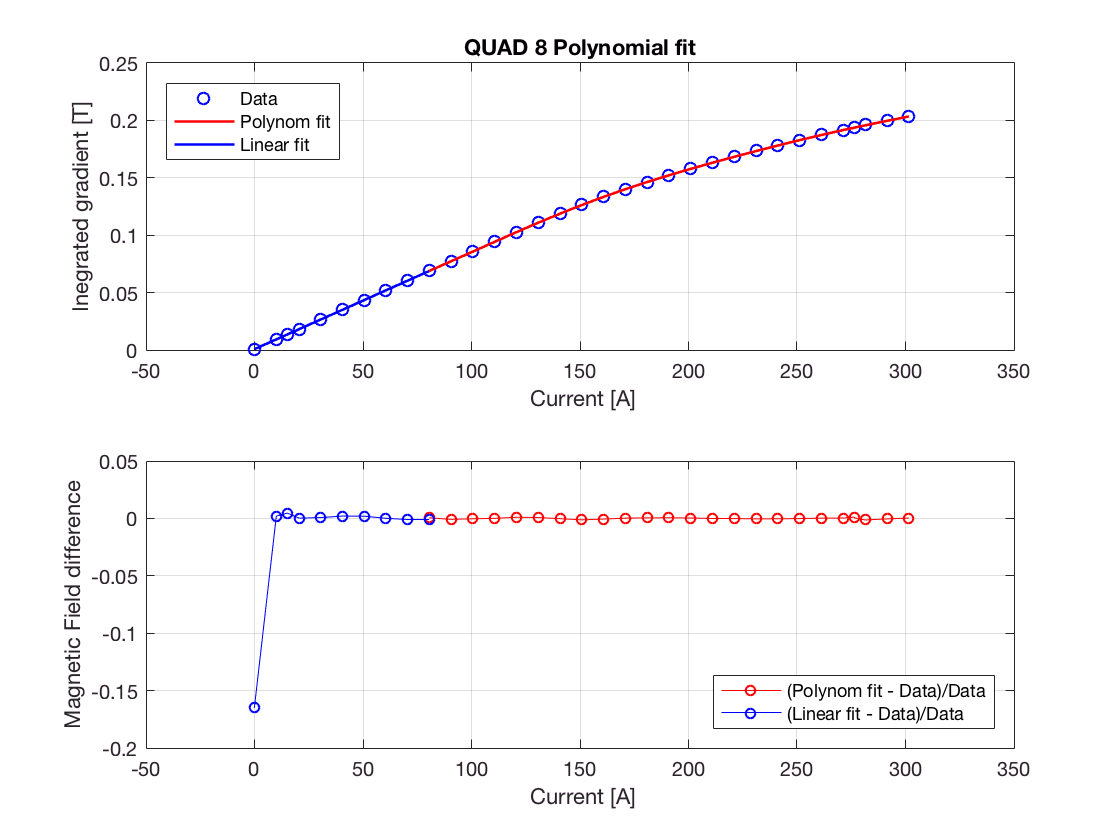



figure
subplot(2,1,1);
set(gca,'FontSize',16)
plot(I9, B9, 'o', 'MarkerSize',6)
hold on
plot(x2, f9, 'r-', 'LineWidth',1.3)
plot(x1, fl9, 'b-', 'LineWidth',1.3)
hold off
title('QUAD 8 Polynomial fit')
xlabel(' Current [A]')
ylabel('Inegrated gradient [T]')
u = legend('Data','Polynom fit','Linear fit');
set(u,'Location','NorthWest')
subplot(2,1,2);
set(gca,'FontSize',16)
plot(I9_reg2,(polyval(p9,I9_reg2) - B9_reg2)./B9_reg2,'ro-',...
     I9_reg1,(polyval(pl9,I9_reg1) - B9_reg1)./B9_reg1,'bo-','MarkerSize',5);
 xlabel(' Current [A]')
ylabel('Magnetic Field difference')
u = legend('(Polynom fit - Data)/Data','(Linear fit - Data)/Data');
set(u,'Location','SouthEast')

%%


% Linear fit
plinear9 = polyfit(I9,B9,1)

plinear9 =     0.0007    0.0122


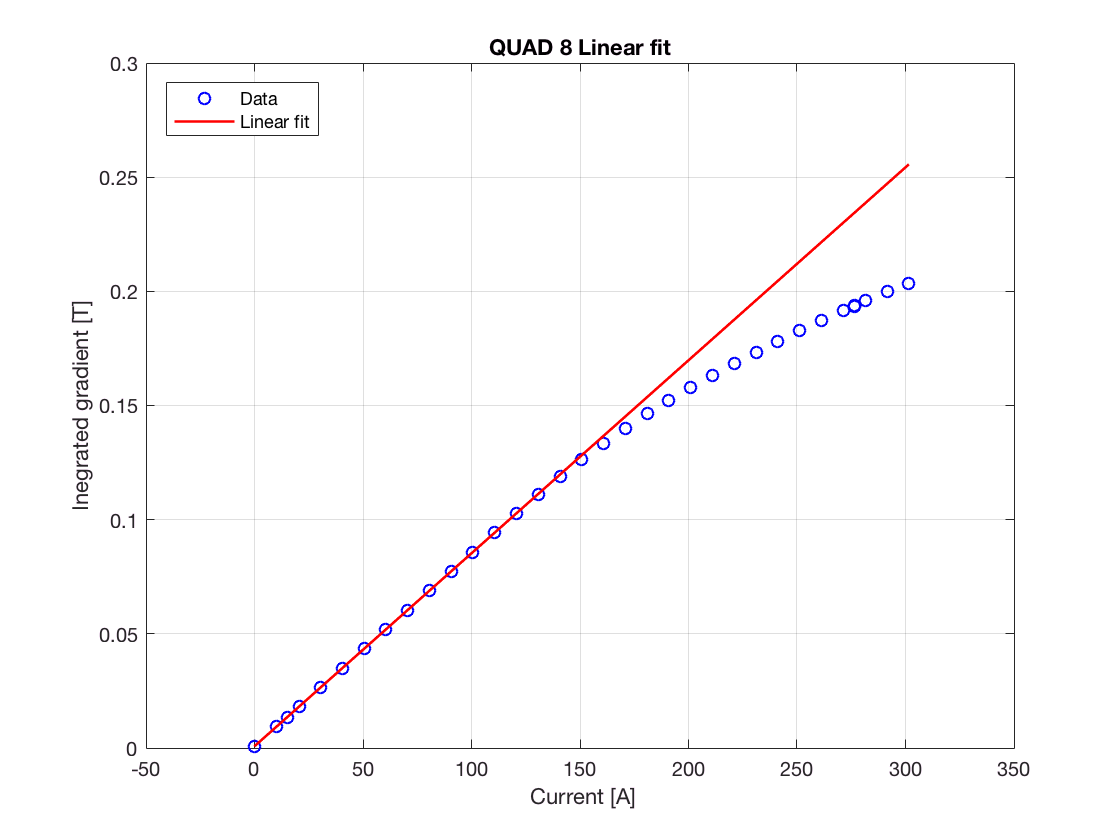


flinear9 = polyval(pl9,xx9);

figure
set(gca,'FontSize',20)
plot(I9, B9, 'o', 'MarkerSize',6)
hold on
plot(xx9, flinear9, 'r-', 'LineWidth',1.3)
%plot(x1, fl9, 'b-', 'LineWidth',1.3)
hold off
title('QUAD 8 Linear fit')
xlabel(' Current [A]')
ylabel('Inegrated gradient [T]')
u = legend('Data','Linear fit');
set(u,'Location','NorthWest')


%% Current range fitting around working point 225 A

B9_reg1 = B9(1:14);
I9_reg1 = I9(1:14);

B9_reg2 = B9(14:end);
I9_reg2 = I9(14:end);

x1 = linspace(min(I9_reg1),max(I9_reg1),5*length(I9_reg1));
x2 = linspace(min(I9_reg2),max(I9_reg2),5*length(I9_reg2));

%%

p9 = polyfit(I9_reg2,B9_reg2,3)

p9 =     0.0000   -0.0000    0.0016   -0.0396



f9 = polyval(p9,x2);

% Linear fit
pl9 = polyfit(I9_reg1,B9_reg1,1)

pl9 =    1.0e-03 *

    0.8441    0.8032



fl9 = polyval(pl9,x1);

T91 = table(I9_reg1,B9_reg1,polyval(pl9,I9_reg1),B9_reg1-polyval(pl9,I9_reg1),100*(polyval(pl9,I9_reg1) - B9_reg1)./B9_reg1,'VariableNames',{'I','B','Fit','FitError','RelFitError'})

T91 =         I            B            Fit         FitError      RelFitError
    _________    __________    __________    ___________    ___________

    -0.062303    0.00085924    0.00075056     0.00010867      -12.648  
       10.056     0.0092497     0.0092917    -4.2052e-05      0.45463  
       15.111      0.013478      0.013559    -8.0212e-05      0.59512  
       20.552      0.018135      0.018152    -1.6657e-05     0.091853  
       30.624      0.026632      0.026654    -2.1972e-05     0.082504  
       40.614      0.035022      0.035087    -6.5006e-05      0.18561  
       50.551      0.043408      0.043475    -6.6637e-05      0.15351  
       60.575      0.051958      0.051936     2.1797e-05    -0.041952  
        70.49      0.060399      0.060305     9.4033e-05     -0.15568  
       80.467      0.068836    


T92 = table(I9_reg2,B9_reg2,polyval(p9,I9_reg2),B9_reg2-polyval(p9,I9_reg2),100*(polyval(p9,I9_reg2) - B9_reg2)./B9_reg2,'VariableNames',{'I','B','Fit','FitError','RelFitError'})

T92 =       I          B         Fit       FitError      RelFitError
    ______    _______    _______    ___________    ___________

    120.74    0.10256    0.10266    -0.00010102      0.098491 
    130.82    0.11082    0.11097     -0.0001498       0.13517 
    140.81    0.11879    0.11877     2.5869e-05     -0.021777 
    150.88    0.12646    0.12621     0.00024443      -0.19329 
       161    0.13352    0.13329     0.00022419      -0.16791 
    170.99    0.14005    0.13992     0.00012341     -0.088121 
    181.07    0.14628    0.14626     2.1639e-05     -0.014792 
    190.99     0.1521    0.15219    -9.0973e-05      0.059812 
    201.02    0.15772    0.15788    -0.00016498        0.1046 
    211.09    0.16315    0.16333    -0.00017932       0.10991 
    221.14    0.16832    0.16851    -0.00018631       0.11069 
    

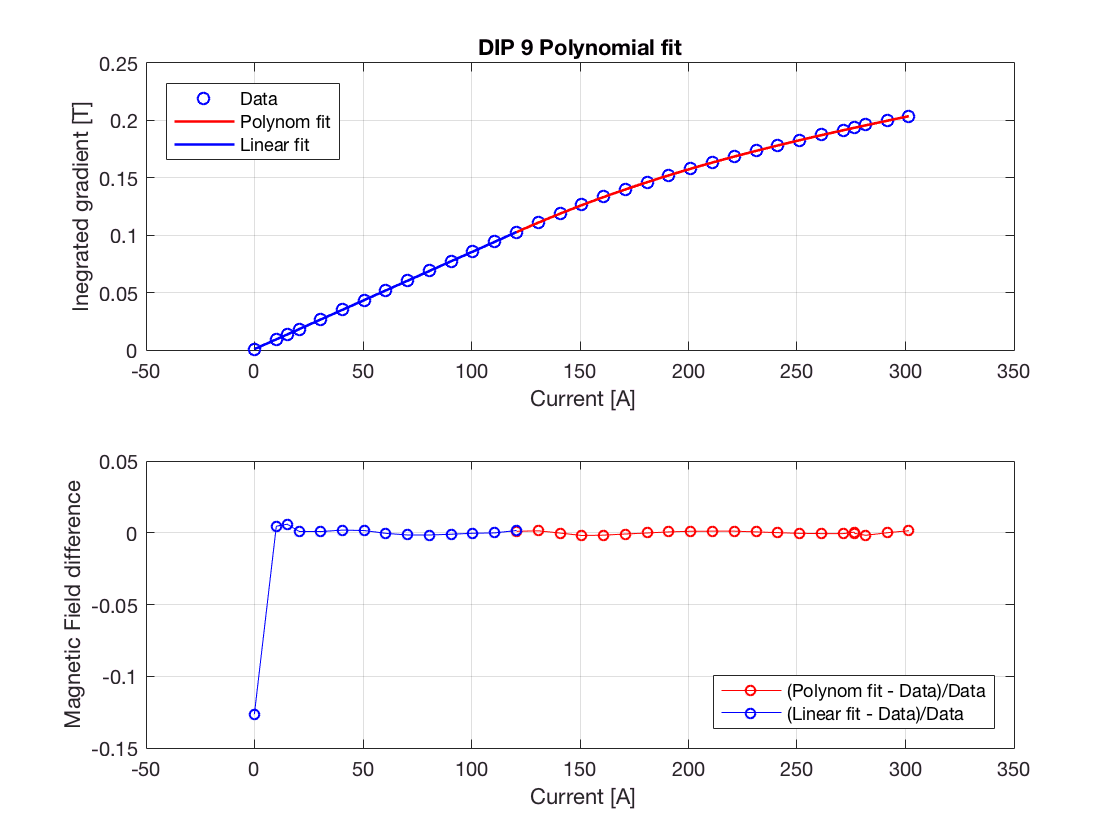



figure
subplot(2,1,1);
set(gca,'FontSize',16)
plot(I9, B9, 'o', 'MarkerSize',6)
hold on
plot(x2, f9, 'r-', 'LineWidth',1.3)
plot(x1, fl9, 'b-', 'LineWidth',1.3)
hold off
title('DIP 9 Polynomial fit')
xlabel(' Current [A]')
ylabel('Inegrated gradient [T]')
u = legend('Data','Polynom fit','Linear fit');
set(u,'Location','NorthWest')
subplot(2,1,2);
set(gca,'FontSize',16)
plot(I9_reg2,(polyval(p9,I9_reg2) - B9_reg2)./B9_reg2,'ro-',...
     I9_reg1,(polyval(pl9,I9_reg1) - B9_reg1)./B9_reg1,'bo-','MarkerSize',5);
 xlabel(' Current [A]')
ylabel('Magnetic Field difference')
u = legend('(Polynom fit - Data)/Data','(Linear fit - Data)/Data');
set(u,'Location','SouthEast')

gev2bend(0.05)

ans = 159.5773

bend2gev(300)

ans = 0.0770